# `Spatio-Temporal Calculation`

## `Adapted from read_data.m, generated form Kundu et. al, written by Dr. Tamas Jozsa`

### `Start`

clear
close all
clc

### `READ CHANNEL PARAMETERS AND SPATIO-TEMPORAL AVERAGES`

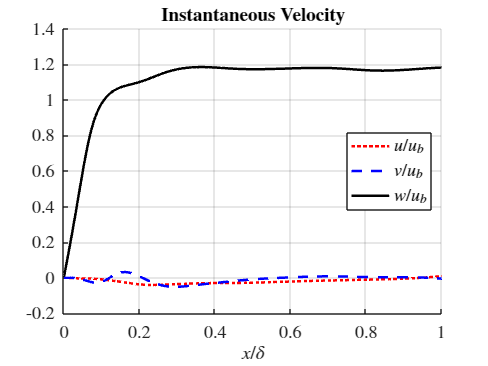

% read parameters
% Lz, Lx, Ly, nu, Delta p
params = xlsread('Reynolds_stresses.xlsx','parameters');

Lz = params(1); Lx = params(2); Ly = params(3);
nu = params(4); % kinematic viscosity


% these values are equal to unity because they are the reference quantities
% used to make the data dimensionless
u_b = 1.0; % bulk velocity (average velocity in the entire channel)
rho = 1.0; % density
delta = Lx/2; % boundary layer thickness  =  channel half-height
mu = nu*rho;

% bulk Reynolds number based on channel half height and mean velocity
Re_b  =  u_b*delta/nu;

% read wall-normal coordinate and spatio-temporal averages
% x, <w>, <w'w'>, <u'u'> , <v'v'>, <u'w'>
ST_ave_dat = xlsread('Reynolds_stresses.xlsx','Reynolds_stresses');


%% READ TIME SAMPLES AT PROBES PLACED ALONG A WALL_NORMAL LINE

hinfo  =  hdf5info('time_samples.hdf5');

% sampling time
t_smpl = hdf5read(hinfo.GroupHierarchy.Datasets(1));
% wall-normal location of the samples
x_smpl = hdf5read(hinfo.GroupHierarchy.Datasets(5))+1.0;

% sampled velocity components
% each row represents a time instant as dictated by t_smpl
% each column represents a spatial location as dictated by x_smpl
w_smpl = hdf5read(hinfo.GroupHierarchy.Datasets(2));
u_smpl = hdf5read(hinfo.GroupHierarchy.Datasets(3));
v_smpl = hdf5read(hinfo.GroupHierarchy.Datasets(4));


%% instantaneous velocity plots
figure(1)
title('$\textbf{Instantaneous Velocity}$','Interpreter','latex','FontSize',14)
hold on
plot(x_smpl,u_smpl(1,:),':r',LineWidth=2)
plot(x_smpl,v_smpl(1,:),'--b',LineWidth=2)
plot(x_smpl,w_smpl(1,:),'-k',LineWidth=2)
xlabel('$x/\delta$','Interpreter','latex','FontSize',14)
xlim([0,1])
ylim([-0.2,1.4])
legend('$u/u_b$','$v/u_b$','$w/u_b$',...
    'Interpreter','latex','FontSize',14,'Location','east')
set(gca,'TickLabelInterpreter','latex','FontSize',14)
grid on
hold off

## `Mean Streamwise Velocity Component`

`Because the normal is mostly regarding the u component, it can be seen that u component is prominent compared to the two other components. `

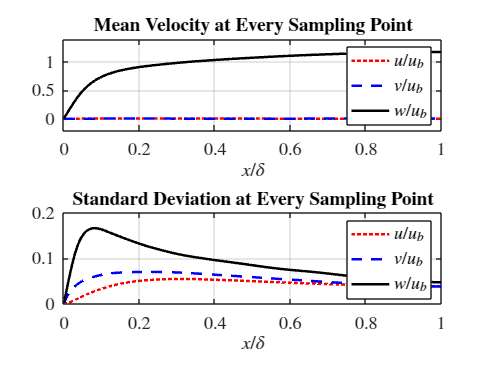

%u-velocity sampling
u_mean = mean(u_smpl, 1);
u_std = std(u_smpl);

%v-velocity sampling
v_mean = mean(v_smpl, 1);
v_std = std(v_smpl);


%w-velocity sampling
w_mean = mean(w_smpl, 1);
w_std = std(w_smpl);

% Create figure for the combined plot
figure(2);

% First subplot: Mean Velocity at Every Sampling Point
subplot(2,1,1);
plot(x_smpl, u_mean, ':r', 'LineWidth', 2);
hold on;
plot(x_smpl, v_mean, '--b', 'LineWidth', 2);
plot(x_smpl, w_mean, '-k', 'LineWidth', 2);
title('$\textbf{Mean Velocity at Every Sampling Point}$', 'Interpreter', 'latex', 'FontSize', 14);
xlabel('$x/\delta$', 'Interpreter', 'latex', 'FontSize', 14);
xlim([0, 1]);
ylim([-0.2, 1.4]);
legend('$u/u_b$', '$v/u_b$', '$w/u_b$', 'Interpreter', 'latex', 'FontSize', 14, 'Location', 'east');
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 14);
grid on;
hold off;

% Second subplot: Standard Deviation at Every Sampling Point
subplot(2,1,2);
plot(x_smpl, u_std, ':r', 'LineWidth', 2);
hold on;
plot(x_smpl, v_std, '--b', 'LineWidth', 2);
plot(x_smpl, w_std, '-k', 'LineWidth', 2);
title('$\textbf{Standard Deviation at Every Sampling Point}$', 'Interpreter', 'latex', 'FontSize', 14);
xlabel('$x/\delta$', 'Interpreter', 'latex', 'FontSize', 14);
xlim([0, 1]);
legend('$u/u_b$', '$v/u_b$', '$w/u_b$', 'Interpreter', 'latex', 'FontSize', 14, 'Location', 'east');
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 14);
grid on;
hold off;

## `Wall Normal Mean Streamwise Velocity Gradient`

`At this case, `$w/u_{b}$` is the only velocity component that has values in wall-normal direction. The other two has near zero value and thus can be ignored (will have zero gradient in all location)`

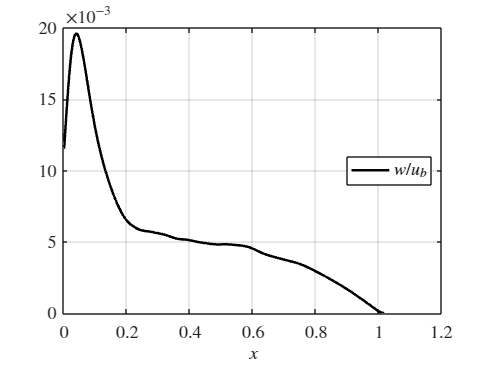

w_grad = gradient(w_mean);
figure(4)
plot(x_smpl, w_grad, '-k', 'LineWidth', 2)
title('$\textbf{Mean Streamwise Velocity Gradient}$', 'Interpreter', 'latex', 'FontSize', 14)
xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 14)
legend('$w/u_b$', 'Interpreter', 'latex', 'FontSize', 14, 'Location', 'east')
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 14)

% Get the handle to the title object
title_handle = title('$\textbf{Mean Streamwise Velocity Gradient}$', 'Interpreter', 'latex', 'FontSize', 14);
set(title_handle, 'Position', get(title_handle, 'Position') + [0 0.01 0]); % Adjust the vertical position
grid on
hold off

## `Analytical`

`To capture the nearly identical profile to the numerical result, von Kármán log velocity profile is used instead of the usual elliptical profile. `

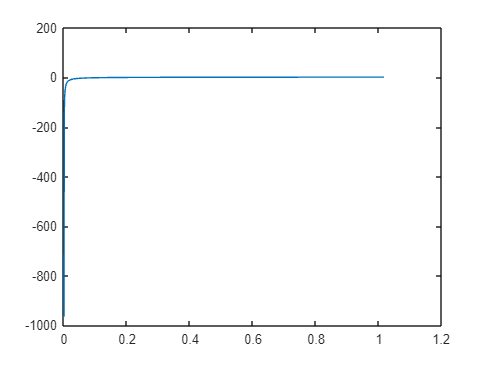

%von Kármán Log Velocity Profile
c_f = 0.026/(Re_b)^(1/7);
tau_w = 0.5*c_f*rho*u_b^2;
u_t = 0;
v_t = 0;
w_t = sqrt(tau_w/rho);
delta_v = nu/w_t;
kappa = 0.41;
y0 = kappa*delta_v;

syms y
% Calculate the mean streamwise velocity using the von Kármán logarithmic law
u_a = (u_t / kappa) * log(y / y0);
v_a = (v_t / kappa) * log(y / y0);
w_a = (w_t / kappa) * log(y / y0);

digits(5)


h = (x_smpl(2)-x_smpl(1))/2;
res_w_a_1 = subs(w_a, y, x_smpl);
res_w_a_minh = subs(w_a, y, x_smpl-h);
res_w_a_plush = subs(w_a, y, x_smpl+h);

difrnt = vpa((res_w_a_plush-res_w_a_minh)/(2*h));
d_difrnt = double(real(difrnt));

%Richardson Extrapolation
RE = 4*(res_w_a_1-difrnt)/3;
d_re = double(real(RE));
figure;
hold off
plot(x_smpl, d_re)

### `Richardson Extrapolation`

`Used for calculating the derivative of an equation. In this case, velocity gradient is obtained by using Richardson Extrapolation on the von Karman log velocity profile.`

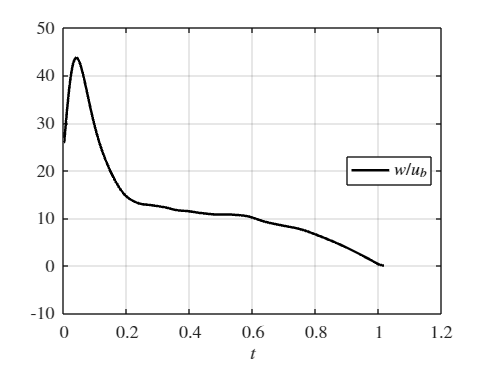

% Finding the given data step size, considering equidistant sampling
h1 = (x_smpl(2) - x_smpl(1))/1;
w_grad_h1 = gradient(w_mean, h1);

% Determining the finer step size for Richardson extrapolation
h2 = h1/2;
w_grad_h2 = gradient(w_mean, h2);

%Richardson Extrapolation for the gradient
%Assuming second-order convergence
w_grad_richardson = (4 * w_grad_h2 - w_grad_h1) / 3;

% Plot the Richardson-extrapolated gradient
figure;
plot(x_smpl, w_grad_richardson, '-k', 'LineWidth', 2);
xlabel('$t$', 'Interpreter', 'latex', 'FontSize', 14);
legend('$w/u_b$', 'Interpreter', 'latex', 'FontSize', 14, 'Location', 'east');
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 14);
grid on;

%Make new array of numerical result;
n = length(w_mean);

% Create an array with zeros (or NaN) interleaved
int_x_smpl = NaN(1, 2*n);
int_x_smpl(1:2:end) = w_mean;

% Replace zeros (or NaN) with the average of the neighboring elements
for i = 2:2:2*n-2
    int_x_smpl(i) = (int_x_smpl(i-1) + int_x_smpl(i+1))/2;
end

int_x_smpl(end) = 0;  % Set the last element to zero
int_x_smpl(end) = int_x_smpl(end-1);  % Set the last element to the second last element






### `FFT Transformation at x = 0.06 location`

`Because of the value of the numerical solution array has no exact x = 0.06 value, the index of which the value is the closest needs to be determined prior to the calculation `

%Finding the position of x = 0.06 in the x_smpl array
specified_value = 0.06;

% Find the index of the element in the array closest to the specified value
[~, index] = min(abs(x_smpl - specified_value));

% Display the index and the value in the array that is closest to the specified value
closest_value = x_smpl(index);
disp(['Index of closest element: ', num2str(index)]);

Index of closest element: 34


disp(['Value in the array closest to ', num2str(specified_value), ': ', num2str(closest_value)]);

Value in the array closest to 0.06: 0.060999


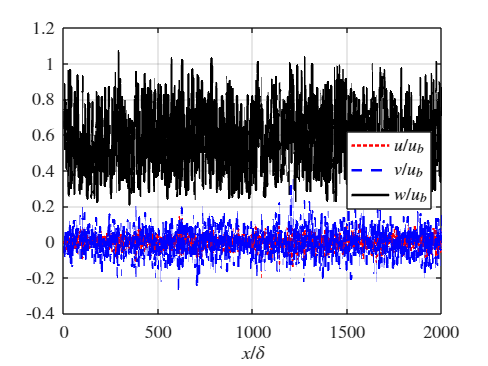


%Plot the noisy signal with time
u_int_area = u_smpl(:, index);
v_int_area = v_smpl(:, index);
w_int_area = w_smpl(:, index);

figure(6)
title('$\textbf{Wall Normal Velocity Signal}$','Interpreter','latex','FontSize',14)
plot(t_smpl,u_int_area,':r',LineWidth=2)
hold on
plot(t_smpl,v_int_area,'--b',LineWidth=2)
plot(t_smpl,w_int_area,'-k',LineWidth=2)
xlabel('$x/\delta$','Interpreter','latex','FontSize',14)
legend('$u/u_b$','$v/u_b$','$w/u_b$',...
    'Interpreter','latex','FontSize',14,'Location','east')
set(gca,'TickLabelInterpreter','latex','FontSize',14)
grid on
hold off

`Then the FFT transformation can be made.`

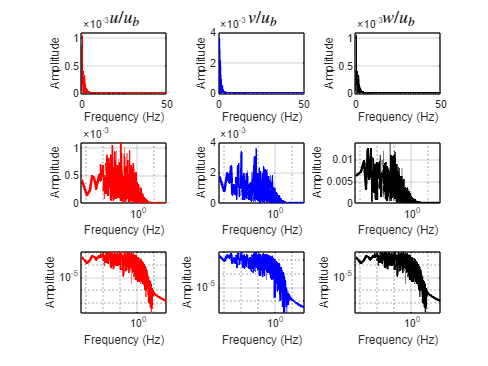

% Compute FFT 
Fs = 1 / (t_smpl(2) - t_smpl(1));  % Sampling frequency
L = length(u_int_area);  % Length of the signal

%Computing standard FFT
u_fft = fft(u_int_area);
P2_u_fft = abs(u_fft / L);
P1_u_fft = P2_u_fft(1:L/2+1);
f_u_fft = Fs*(0:(L/2))/L;

v_fft = fft(v_int_area);
P2_v_fft = abs(v_fft / L);
P1_v_fft = P2_v_fft(1:L/2+1);
f_v_fft = Fs*(0:(L/2))/L;

w_fft = fft(w_int_area);
P2_w_fft = abs(w_fft / L);
P1_w_fft = P2_w_fft(1:L/2+1);
f_w_fft = Fs*(0:(L/2))/L;

figure(7)
fftlin_1 = subplot (3,3,1);
plot(f_u_fft, P1_u_fft, 'r', 'LineWidth', 2)
title('\textbf{$u/u_b$}','Interpreter','latex','FontSize',14)
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

fftlin_2 = subplot(3,3,2);
plot(f_v_fft, P1_v_fft, 'b', 'LineWidth', 2)
title('\textbf{$v/u_b$}', 'Interpreter', 'latex', 'FontSize', 14)
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

fftlin_3 = subplot(3,3,3);
plot(f_u_fft, P1_u_fft, 'k', 'LineWidth', 2)
title('\textbf{$w/u_b$}', 'Interpreter', 'latex', 'FontSize', 14)
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;



fftsl_1 = subplot (3,3,4);
semilogx(f_u_fft, P1_u_fft, 'r', 'LineWidth', 2)
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

fftsl_2 = subplot(3,3,5);
semilogx(f_v_fft, P1_v_fft, 'b', 'LineWidth', 2)
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

fftsl_3 = subplot(3,3,6);
semilogx(f_w_fft, P1_w_fft, 'k', 'LineWidth', 2)
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;


fftlog_1 = subplot(3,3,7);
loglog(f_u_fft, P1_u_fft, 'r', 'LineWidth', 2)
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

fftlog_2 = subplot(3,3,8);
loglog(f_v_fft, P1_v_fft, 'b', 'LineWidth', 2)
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

fftlog_3 = subplot(3,3,9);
loglog(f_u_fft, P1_u_fft, 'k', 'LineWidth', 2)
xlabel('Frequency (Hz)');
ylabel('Amplitude');
grid on;

hold off

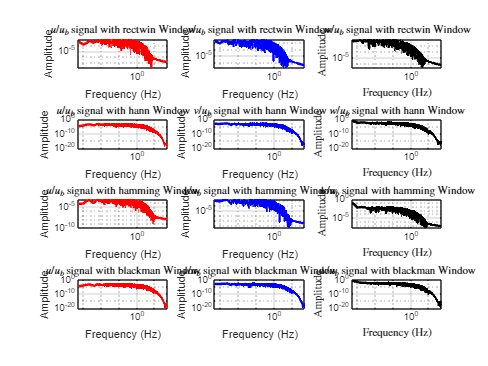



% Apply window functions to the signals
window_types = {'rectwin', 'hann', 'hamming', 'blackman'}; % Window types to try

figure;
for i = 1:length(window_types)
    windowed_u = u_int_area .* feval(window_types{i}, length(u_int_area)); % Apply window function to u_int_area
    windowed_v = v_int_area .* feval(window_types{i}, length(v_int_area)); % Apply window function to v_int_area
    windowed_w = w_int_area .* feval(window_types{i}, length(w_int_area)); % Apply window function to w_int_area
    
    % Compute single-sided FFT for windowed signals
    Y_u = fft(windowed_u);
    P2_u = abs(Y_u / L);
    P1_u = P2_u(1:L/2+1);
    f_u = Fs*(0:(L/2))/L;

    Y_v = fft(windowed_v);
    P2_v = abs(Y_v / L);
    P1_v = P2_v(1:L/2+1);
    f_v = Fs*(0:(L/2))/L;

    Y_w = fft(windowed_w);
    P2_w = abs(Y_w / L);
    P1_w = P2_w(1:L/2+1);
    f_w = Fs*(0:(L/2))/L;

    subplot(length(window_types),3,3*i-2);
    loglog(f_u, P1_u, 'r', 'LineWidth', 2);
    title(['$u/u_b$ signal with ', window_types{i}, ' Window'], 'Interpreter','latex');
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    grid on;

    subplot(length(window_types),3,3*i-1);
    loglog(f_v, P1_v, 'b', 'LineWidth', 2);
    title(['$v/u_b$ signal with ', window_types{i}, ' Window'], 'Interpreter','latex');
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    grid on;

    subplot(length(window_types),3,3*i);
    loglog(f_w, P1_w, 'k', 'LineWidth', 2);
    title(['$w/u_b$ signal with ', window_types{i}, ' Window'], 'Interpreter','latex');
    xlabel('Frequency (Hz)', 'Interpreter','latex');
    ylabel('Amplitude', 'Interpreter','latex');
    grid on;
end

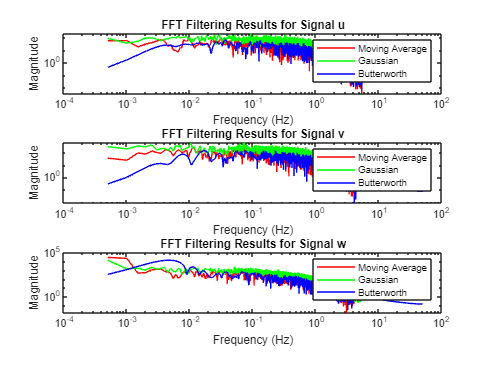

% Define parameters for filtering
filter_order = 4;  % Butterworth filter order
cutoff_frequency = 0.1;  % Butterworth filter cutoff frequency normalized to Nyquist frequency

% Perform FFT and apply different filters for u, v, and w
u_fft_ma = movmean(u_fft, 5);  % Moving average filtering for u
v_fft_ma = movmean(v_fft, 5);  % Moving average filtering for v
w_fft_ma = movmean(w_fft, 5);  % Moving average filtering for w

u_fft_gaussian = imgaussfilt(abs(u_fft));  % Gaussian filtering for u
v_fft_gaussian = imgaussfilt(abs(v_fft));  % Gaussian filtering for v
w_fft_gaussian = imgaussfilt(abs(w_fft));  % Gaussian filtering for w

[b, a] = butter(filter_order, cutoff_frequency);  % Butterworth filter coefficients
u_fft_butter = filter(b, a, u_fft);  % Butterworth filtering for u
v_fft_butter = filter(b, a, v_fft);  % Butterworth filtering for v
w_fft_butter = filter(b, a, w_fft);  % Butterworth filtering for w

% Plotting the results in one figure
figure;

subplot(3, 1, 1);
loglog(f_u_fft, abs(u_fft_ma(1:L/2+1)), 'r', f_u_fft, abs(u_fft_gaussian(1:L/2+1)), 'g', f_u_fft, abs(u_fft_butter(1:L/2+1)), 'b');
title('FFT Filtering Results for Signal u');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Moving Average', 'Gaussian', 'Butterworth');

subplot(3, 1, 2);
loglog(f_v_fft, abs(v_fft_ma(1:L/2+1)), 'r', f_v_fft, abs(v_fft_gaussian(1:L/2+1)), 'g', f_v_fft, abs(v_fft_butter(1:L/2+1)), 'b');
title('FFT Filtering Results for Signal v');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Moving Average', 'Gaussian', 'Butterworth');

subplot(3, 1, 3);
loglog(f_w_fft, abs(w_fft_ma(1:L/2+1)), 'r', f_w_fft, abs(w_fft_gaussian(1:L/2+1)), 'g', f_w_fft, abs(w_fft_butter(1:L/2+1)), 'b');
title('FFT Filtering Results for Signal w');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
legend('Moving Average', 'Gaussian', 'Butterworth');

## `Skewness and Kurtosis`

usmplvect = u_smpl(:);
vsmplvect = v_smpl(:);
wsmplvect = w_smpl(:);

% Normality tests
fprintf('Skewness of u_smpl: %.4f\n', skewness(usmplvect(:)));

Skewness of u_smpl: 0.2336


fprintf('Kurtosis of u_smpl: %.4f\n', kurtosis(usmplvect(:)));

Kurtosis of u_smpl: 5.2884



fprintf('Skewness of v_smpl: %.4f\n', skewness(vsmplvect(:)));

Skewness of v_smpl: -0.0045


fprintf('Kurtosis of v_smpl: %.4f\n', kurtosis(vsmplvect(:)));

Kurtosis of v_smpl: 4.2443



fprintf('Skewness of w_smpl: %.4f\n', skewness(wsmplvect(:)));

Skewness of w_smpl: -0.6988


fprintf('Kurtosis of w_smpl: %.4f\n', kurtosis(wsmplvect(:)));

Kurtosis of w_smpl: 2.1419


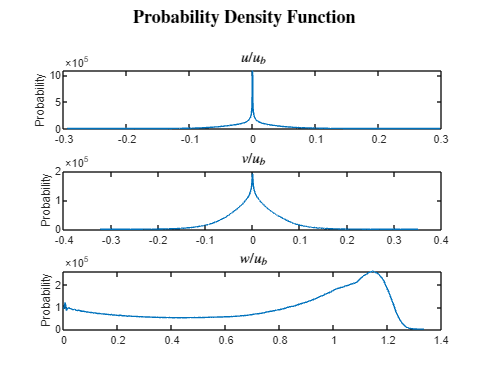


% Calculate the histogram
[countsu, edgesu] = histcounts(usmplvect);
[countsv, edgesv] = histcounts(vsmplvect);
[countsw, edgesw] = histcounts(wsmplvect);

% Define the range of x values
x_values_u = edgesu(1:end-1);
x_values_v = edgesv(1:end-1);
x_values_w = edgesw(1:end-1);

% Create a figure with a 3-by-1 grid of subplots
figure;
sgtitle('\textbf{Probability Density Function}','Interpreter', 'latex', 'FontSize', 14)
% Plot the PDF of u_smpl in the first subplot
ax1 = subplot(3,1,1);
plot(x_values_u, countsu);
ylabel('Probability');
title('$u/u_b$', 'Interpreter', 'latex', 'FontSize', 12);

% Plot the PDF of v_smpl in the second subplot
ax2 = subplot(3,1,2);
plot(x_values_v, countsv);
ylabel('Probability');
title('$v/u_b$', 'Interpreter', 'latex', 'FontSize', 12');

% Plot the PDF of w_smpl in the third subplot
ax3 = subplot(3,1,3);
plot(x_values_w, countsw);
ylabel('Probability');
title('$w/u_b$', 'Interpreter', 'latex', 'FontSize', 12');

% Correlation analysis
alpha = 0.05; % Significance level
[r_uv, p_uv] = corrcoef(u_smpl(:), v_smpl(:));
[r_uw, p_uw] = corrcoef(u_smpl(:), w_smpl(:));
[r_vw, p_vw] = corrcoef(v_smpl(:), w_smpl(:));

fprintf('Correlation between u_smpl and v_smpl: %.4f (p-value: %.4f)\n', r_uv(1,2), p_uv(1,2));

Correlation between u_smpl and v_smpl: -0.0017 (p-value: 0.0000)


fprintf('Correlation between u_smpl and w_smpl: %.4f (p-value: %.4f)\n', r_uw(1,2), p_uw(1,2));

Correlation between u_smpl and w_smpl: -0.1093 (p-value: 0.0000)


fprintf('Correlation between v_smpl and w_smpl: %.4f (p-value: %.4f)\n', r_vw(1,2), p_vw(1,2));

Correlation between v_smpl and w_smpl: 0.0081 (p-value: 0.0000)
